# Question1

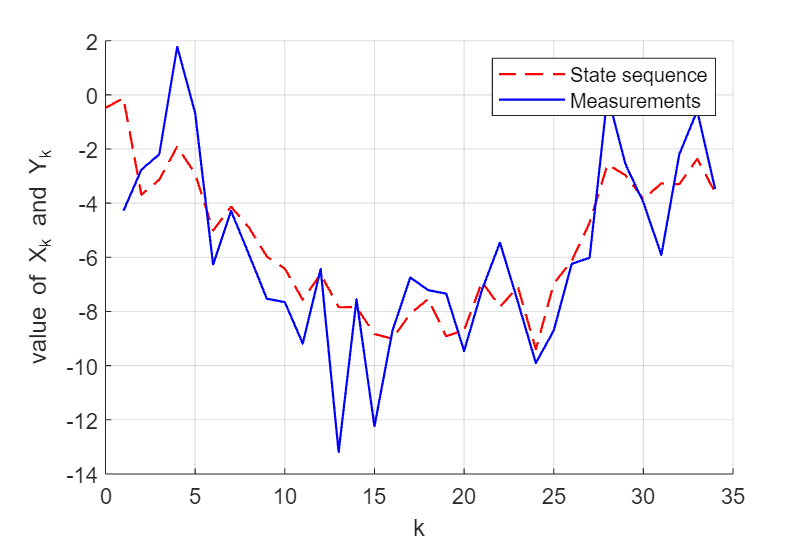

%(a)
%X_k=A*X_{k-1}+q_{k-1}, q_{k-1}~N(0,Q)
% Y_k=H*X_k+r_k, r_k~N(0,R)
Q=1.5;R=3;A=1;H=1;
x_0=2;P_0=8;N=35;
X_k1= genLinearStateSequence(x_0, P_0, A, Q, N);
Y_k1= genLinearMeasurementSequence(X_k1, H, R);
figure('Position',[300 300 600 400]);hold on;
plot(0:N-1,X_k1(1,1:N), '--k','Color','red',LineWidth=1);
plot(1:N-1, Y_k1(1,1:N-1),'Color','blue',LineWidth=1);
grid on
legend('State sequence', 'Measurements')
xlabel('k');
ylabel('value of X_{k} and Y_{k}');
hold off

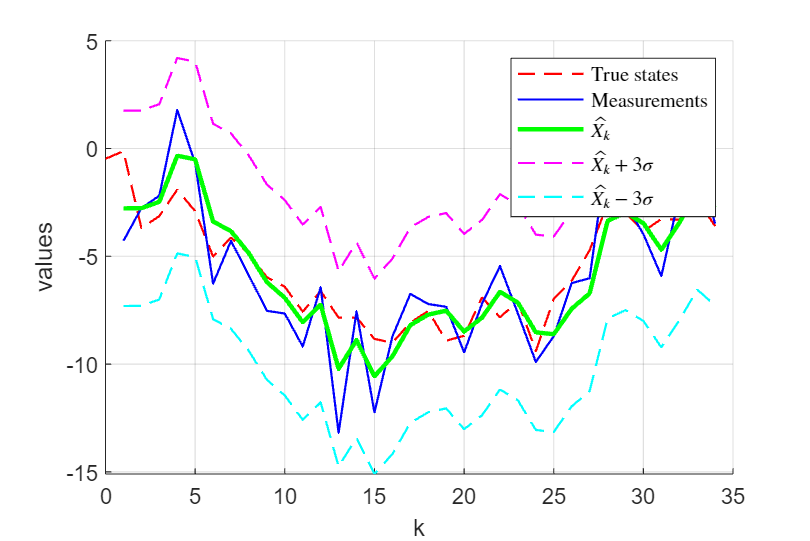

%(b)
[X_estimate, P_estimate,~,~,~] = kalmanFilter(Y_k1, x_0, P_0, A, Q, H, R);
X_true =X_k1;
x_3sigma1=X_estimate+3*sqrt(P_estimate);
x_3sigma2=X_estimate-3*sqrt(P_estimate);
figure('Position',[300 300 600 400]);hold on;
plot(0:N-1,X_true(1,1:N), '--k','Color','red',LineWidth=1);
plot(1:N-1, Y_k1(1,1:N-1),'Color','blue',LineWidth=1);
plot(1:N-1, X_estimate(1,1:N-1),'Color','green',LineWidth=2);
plot(1:N-1, x_3sigma1(1,1:N-1), '--k','Color','m',LineWidth=1);
plot(1:N-1, x_3sigma2(1,1:N-1), '--k','Color','cyan',LineWidth=1);
grid on
legend('True states', 'Measurements','$\hat{X_k}$','$\hat{X_k}+3\sigma$','$\hat{X_k}-3\sigma$','Interpreter','latex')
xlabel('k');
ylabel('values');
hold off

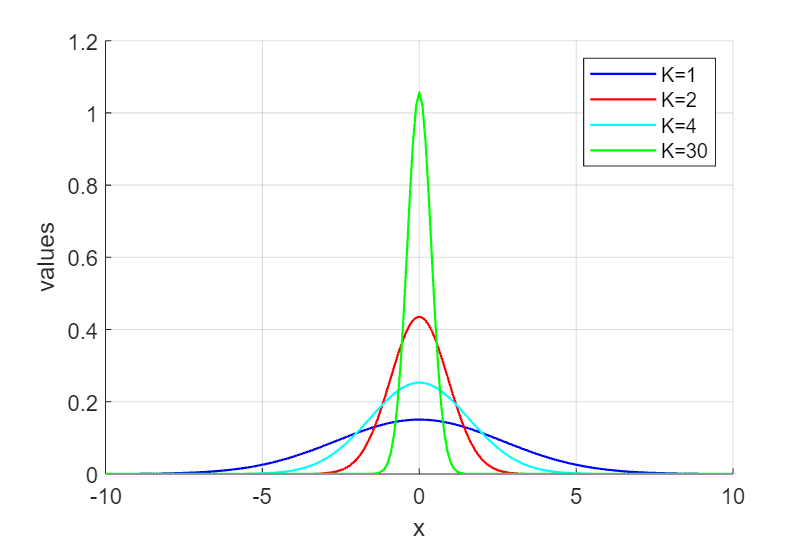

mu=0;value=10;K=[1,2,4,30];
Y_densty=[];
for i=1:length(K)
    variance=(X_true(:,K(i)+1)-X_estimate(:,K(i)))^2;
    [x_plot,Y1]=normPlot(value,mu,variance);
    Y_densty=[Y_densty;Y1];
end
figure('Position',[300 300 600 400]);hold on;
plot(x_plot,Y_densty(1,:),'LineWidth',1,'color','blue');
plot(x_plot,Y_densty(2,:),'LineWidth',1,'color','red');
plot(x_plot,Y_densty(3,:),'LineWidth',1,'color','cyan');
plot(x_plot,Y_densty(4,:),'LineWidth',1,'color','green');
legend('K=1', 'K=2','K=4','K=30');
grid on
xlabel('x');
ylabel('values');
hold off

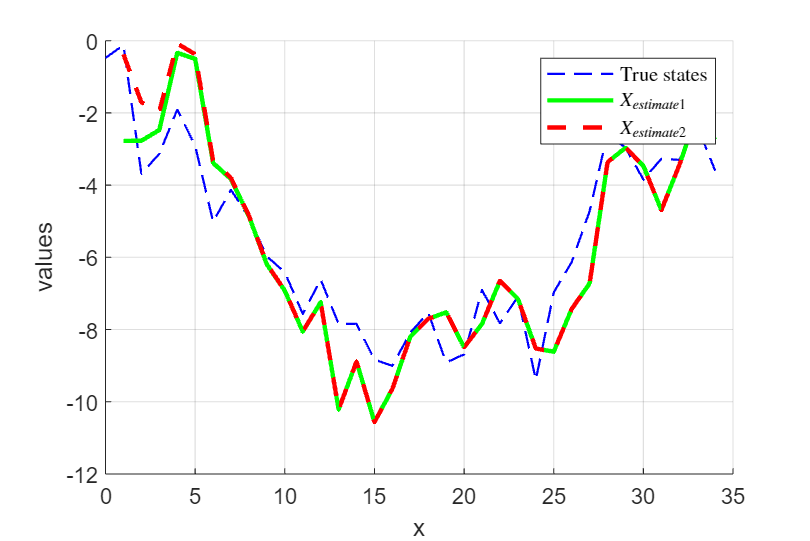

%(c)
X_NEW=12;
[X_estimate2, ~,~,~,~] = kalmanFilter(Y_k1, X_NEW, P_0, A, Q, H, R);
figure('Position',[300 300 600 400]);hold on;
plot(0:N-1,X_true(1,1:N), '--k','Color','blue',LineWidth=1);
plot(1:N-1, X_estimate(1,1:N-1),'Color','green',LineWidth=2);
plot(1:N-1, X_estimate2(1,1:N-1),'--k','Color','red',LineWidth=2);
legend('True states','$X_{estimate1}$', '$X_{estimate2}$','Interpreter','latex');
grid on
xlabel('x');
ylabel('values');
hold off

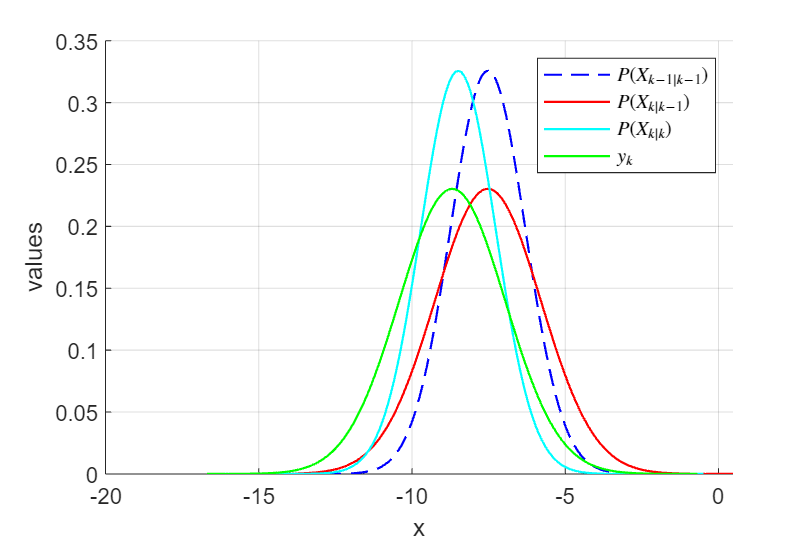

%(d)
%X_k=A*X_{k-1}+q_{k-1}, q_{k-1}~N(0,Q)
% Y_k=H*X_k+r_k, r_k~N(0,R)
%Q=1.5;R=3;A=1;H=1;
%x_0=2;P_0=8;N=35;P(x0)=N(x0;x_0,P_0)
%let K=34
k=20;value=8;
[X_estimate, P_estimate, X_predict, P_predict,~] = kalmanFilter(Y_k1, X_NEW, P_0, A, Q, H, R);
[x_plot1,X1]=normPlot(value,X_estimate(:,k-1),P_estimate(:,k-1));
[x_plot2,X2]=normPlot(value,X_predict(:,k),P_predict(:,k-1));
[x_plot3,X3]=normPlot(value,X_estimate(:,k),P_estimate(:,k));
[x_plot4,Y_k]=normPlot(value,X_k1(:,k+1),R);
figure('Position',[300 300 600 400]);hold on;
plot(x_plot1,X1,'--k','LineWidth',1,'color','blue');
plot(x_plot2,X2,'LineWidth',1,'color','red');
plot(x_plot3,X3,'LineWidth',1,'color','cyan');
plot(x_plot4,Y_k,'LineWidth',1,'color','green');
legend('$P(X_{k-1|k-1})$','$P(X_{k|k-1})$','$P(X_{k|k})$','$y_k$','Interpreter','latex');
grid on
xlabel('x');
ylabel('values');
hold off

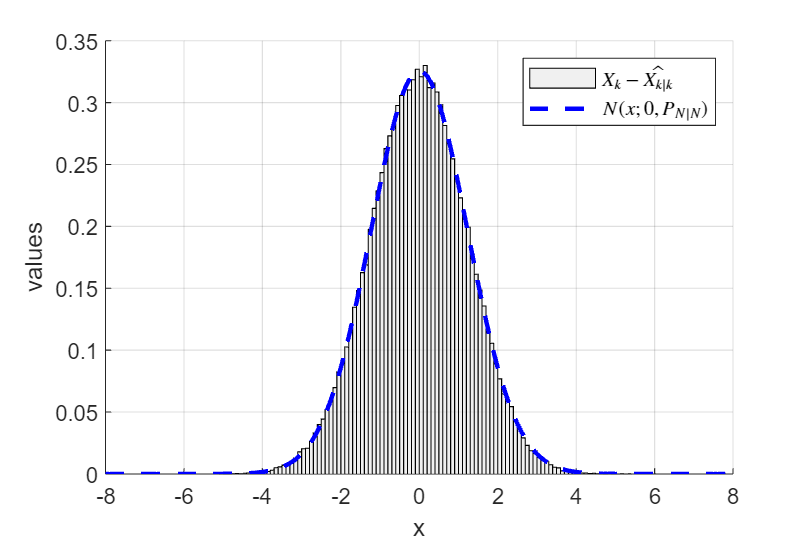

%(e)
%question 1
Q=1.5;R=3;A=1;H=1;
x_0=2;P_0=8;N2=100000;
X_true2= genLinearStateSequence(x_0, P_0, A, Q, N2);
Y_k2= genLinearMeasurementSequence(X_true2, H, R);
[X_estimate3, P_estimate3, ~, ~,~] = kalmanFilter(Y_k2, x_0, P_0, A, Q, H, R);
delta_X=X_true2(:,2:end)-X_estimate3;
figure('Position',[300 300 600 400]);hold on;
histogram(delta_X,'Normalization','pdf','FaceColor',[.9 .9 .9]);
value=8;mu=0;
[x_plote,Ye]=normPlot(value,mu,P_estimate3(:,N2));
plot(x_plote,Ye,'--k','LineWidth',2,'color','blue');
legend('$X_k-\hat{X_{k|k}}$','$N(x;0,P_{N|N})$','Interpreter','latex');
grid on
xlabel('x');
ylabel('values');
hold off

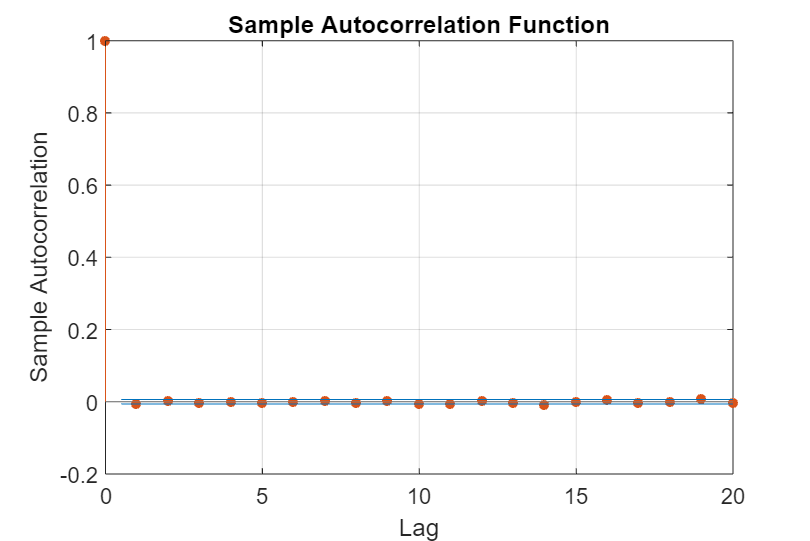

%question 2
[X_estimate3, P_estimate3, ~, ~,VK] = kalmanFilter(Y_k2, x_0, P_0, A, Q, H, R);
autocorr(VK)

# Question2

%2(a)
%ypk=pk+rpk, rpk~N(0,1),measured position
%yvk=C(vk+rvk),C≈1,rvk~N(0,R)
load SensorMeasurements.mat
% [mu_y, Sigma_y] = approxGaussianTransform(CalibrationSequenceVelocity_v10)
[mu_y1, Sigma_y1] = approxGaussianTransform(CalibrationSequenceVelocity_v0)

mu_y1 = -0.0734

Sigma_y1 = 2.9867

[mu_y2, Sigma_y2,C2]=C_calculate(CalibrationSequenceVelocity_v10,10)

mu_y2 = 11.0264

Sigma_y2 = 3.0332

C2 = 1.1026

[mu_y3, Sigma_y3,C3]=C_calculate(CalibrationSequenceVelocity_v20,20)

mu_y3 = 22.0453

Sigma_y3 = 3.0439

C3 = 1.1023

R=(Sigma_y1/C3^2+Sigma_y2/C3^2+Sigma_y3/C3^2)/3

R = 2.4867

%2(b)
SensorData=Generate_y_seq()

SensorData = 1.0e+04 *

    0.0002       NaN   -0.0001       NaN    0.0003       NaN    0.0000       NaN   -0.0001       NaN    0.0000       NaN    0.0003       NaN    0.0002       NaN    0.0001       NaN    0.0001       NaN   -0.0002       NaN   -0.0002       NaN   -0.0001       NaN    0.0002       NaN    0.0001       NaN   -0.0003       NaN    0.0001       NaN   -0.0000       NaN   -0.0000       NaN    0.0001       NaN   -0.0001       NaN    0.0001       NaN   -0.0002       NaN   -0.0001       NaN    0.0002       NaN
    0.0001    0.0001   -0.0002   -0.0002   -0.0003   -0.0000   -0.0001    0.0002   -0.0001   -0.0001   -0.0004   -0.0001   -0.0003   -0.0000   -0.0001    0.0000   -0.0003    0.0000   -0.0001    0.0000    0.0001    0.0000   -0.0002   -0.0003   -0.0002    0.0002    0.0001    0.0001   -0.0002    0.0003    0.0000    0.0005    0.0003   -0.0001    0.0002   -0.0000   -0.0001    0.0002    0.0000   -0.0000    0.0002    0.0003    0.0000    0.0001    0.0001    0.0000   -0.0001    0

%%%%%data process also implemented in KF
k=length(SensorData);
newData=[];
for i=1:k
    if ~isnan(SensorData(:,i))%mod(i,2)~=0
        newData=[newData,SensorData(:,i)];
    end
end
newData

newData = 1.0e+04 *

    0.0002   -0.0001    0.0003    0.0000   -0.0001    0.0000    0.0003    0.0002    0.0001    0.0001   -0.0002   -0.0002   -0.0001    0.0002    0.0001   -0.0003    0.0001   -0.0000   -0.0000    0.0001   -0.0001    0.0001   -0.0002   -0.0001    0.0002    0.0000    0.0001    0.0002   -0.0001    0.0000    0.0002   -0.0001   -0.0002   -0.0001    0.0001    0.0002   -0.0001   -0.0000   -0.0001   -0.0000   -0.0003   -0.0001    0.0001   -0.0000   -0.0001   -0.0002    0.0003   -0.0001    0.0001    0.0000
    0.0001   -0.0002   -0.0003   -0.0001   -0.0001   -0.0004   -0.0003   -0.0001   -0.0003   -0.0001    0.0001   -0.0002   -0.0002    0.0001   -0.0002    0.0000    0.0003    0.0002   -0.0001    0.0000    0.0002    0.0000    0.0001   -0.0001    0.0000    0.0004    0.0000    0.0002   -0.0001    0.0001   -0.0000    0.0000   -0.0001   -0.0001    0.0003   -0.0003   -0.0002   -0.0001   -0.0001    0.0000   -0.0003   -0.0002    0.0002    0.0002    0.0001    0.0001   -0.0002   -0.00

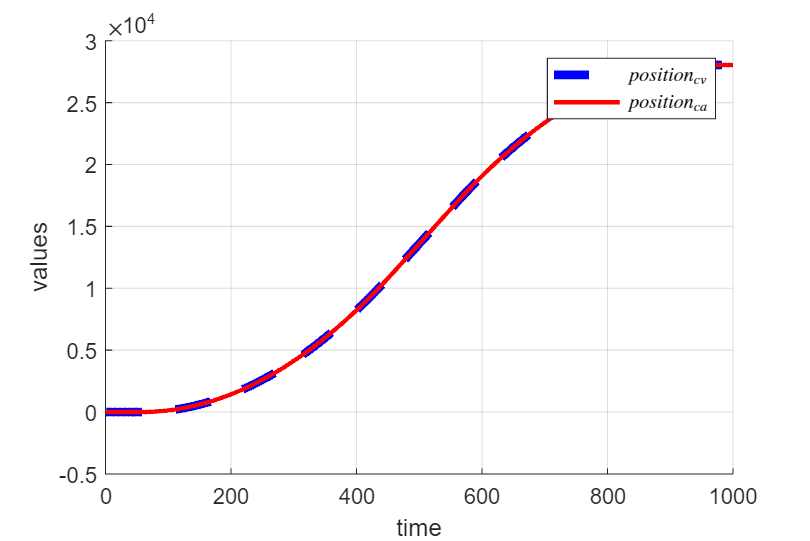

%2(c)
T=0.02;N=1000;
%Constant Velocity Model
A_cv=[1 T;0 1];H=[1 0;0 C3];R1=[1 0;0 C3^2*R];Q=[0.01 0;0 0.01];x_0=[0;0];P_0=[10 0;0 10];
[X_cv, P_cv, ~, ~,~] = kalmanFilter(SensorData, x_0, P_0, A_cv, Q, H, R1);
X_states = genLinearStateSequence(x_0, P_0, A_cv, Q, N);
%Time Constant Acceleratiion Model
A_ca=[1 T T^2;0 1 T;0 0 1];H_ca=[1 0 0;0 C3 0];Q_ca=0.01*eye(3);x_0=[0;0;0];P_0=10*eye(3);
R2=[1 0;0 C3^2*R];
[X_ca, P_ca, ~, ~,~] = kalmanFilter(SensorData, x_0, P_0, A_ca, Q_ca, H_ca, R2);
X_states_ca = genLinearStateSequence(x_0, P_0, A_ca, Q_ca, N);


figure('Position',[300 300 600 400]);hold on;
plot(1:length(X_cv),X_cv(1,:),'--k','LineWidth',4,'color','blue');
% plot(1:length(X_cv),X_states(1,1:N),'LineWidth',2,'color','red');
plot(1:length(X_cv),X_ca(1,:),'LineWidth',2,'color','red');
legend('$position_{cv}$','$position_{ca}$','Interpreter','latex');
grid on
xlabel('time');
ylabel('values');
hold off

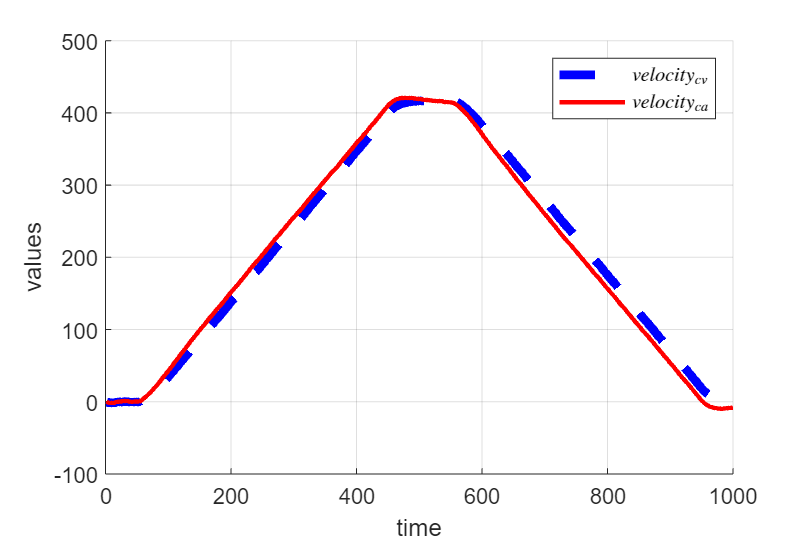

figure('Position',[300 300 600 400]);hold on;
plot(1:length(X_cv),X_cv(2,:),'--k','LineWidth',4,'color','blue');
% plot(1:length(X_cv),X_states(1,1:N),'LineWidth',2,'color','red');
plot(1:length(X_cv),X_ca(2,:),'LineWidth',2,'color','red');
legend('$velocity_{cv}$','$velocity_{ca}$','Interpreter','latex');
grid on
xlabel('time');
ylabel('values');
hold off





% 
% figure('Position',[300 300 600 400]);hold on;
% plot(1:length(X_cv),X_ca(1,:),'--k','LineWidth',2,'color','blue');
% plot(1:length(X_cv),X_states_ca(1,1:N),'LineWidth',2,'color','red');
% legend('$position_{kf}$','$position_s$','Interpreter','latex');
% grid on
% xlabel('time');
% ylabel('values');
% hold off
% figure('Position',[300 300 600 400]);hold on;
% plot(1:length(X_cv),X_ca(2,:),'--k','LineWidth',2,'color','blue');
% plot(1:length(X_cv),X_states_ca(1,1:N),'LineWidth',2,'color','red');
% legend('$velocity_{kf}$','$velocity_s$','Interpreter','latex');
% grid on
% xlabel('time');
% ylabel('values');
% hold off
%Input:
%   Y           [m x N] Measurement sequence
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   H           [m x n] Measurement model matrix
%   R           [m x m] Measurement noise covariance
%


# Function of approxGaussian

function [mu_y, Sigma_y,C]=C_calculate(data,vk)
[mu_y, Sigma_y] = approxGaussianTransform(data);
C=mu_y/vk;
end
function [mu_y, Sigma_y] = approxGaussianTransform(data)
N=length(data);
mu_y=mean(data,2);
Sigma_y=(data-mu_y)*(data-mu_y)'/(N-1);
end

# Function of normpdf

function [x,Y]=normPlot(value,mu,variance)
%GENLINEARSTATESEQUENCE generates an N-long sequence of states using a 
%    Gaussian prior and a linear Gaussian process model
%
%Input:
%   mu         mean
%   X_true     true value of X
%   X_estimate          estimate value from kalman filter
%   k           sample time
%   value       domain 
%
%Output:
%   Y           normpdf of Y
%
% variance=(X_true(:,k+1)-X_estimate(:,k))^2;
x=[mu-value:0.1:mu+value];
Y=normpdf(x,mu,sqrt(variance));
end

# function of kalman filter

function X = genLinearStateSequence(x_0, P_0, A, Q, N)
%GENLINEARSTATESEQUENCE generates an N-long sequence of states using a 
%    Gaussian prior and a linear Gaussian process model
%
%Input:
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   N           [1 x 1] Number of states to generate
%
%Output:
%   X           [n x N+1] State vector sequence
%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
X0= mvnrnd(x_0, P_0)';
% disp(size(X0))
% disp(X0)
X=X0;
for i=1:N
    q=mvnrnd(zeros(length(x_0),1), Q)';
    X=[X A*X(:,i)+q];
end
% disp(X)
% Your code here
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end
function Y = genLinearMeasurementSequence(X, H, R)
%GENLINEARMEASUREMENTSEQUENCE generates a sequence of observations of the state 
% sequence X using a linear measurement model. Measurement noise is assumed to be 
% zero mean and Gaussian.
%
%Input:
%   X           [n x N+1] State vector sequence. The k:th state vector is X(:,k+1)
%   H           [m x n] Measurement matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   Y           [m x N] Measurement sequence
%
Y=[];
for i=2:length(X)
    Y=[Y, H*X(:,i)+mvnrnd(zeros(length(R),1),R)'];
end
% your code here
end
function [x, P] = linearPrediction(x, P, A, Q)
%LINEARPREDICTION calculates mean and covariance of predicted state
%   density using a liear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%
%Output:
%   x           [n x 1] predicted state mean
%   P           [n x n] predicted state covariance
%
x=A*x;
P=A*P*A'+Q;
% Your code here
end
function [x, P,VK] = linearUpdate(x, P, y, H, R)
%LINEARPREDICTION calculates mean and covariance of predicted state
%   density using a linear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   y           [m x 1] Measurement
%   H           [m x n] Measurement model matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   x           [n x 1] updated state mean
%   P           [n x n] updated state covariance
%
SK=H*P*H'+R;
KK=P*H'*inv(SK);
VK=y-H*x;
x=x+KK*VK;
P=P-KK*SK*KK';
% Your code here

end
function [X, P, X_pred, P_pred,VK] = kalmanFilter(Y, x_0, P_0, A, Q, H, R)
%KALMANFILTER Filters measurements sequence Y using a Kalman filter. 
%
%Input:
%   Y           [m x N] Measurement sequence
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   H           [m x n] Measurement model matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   x           [n x N] Estimated state vector sequence
%   P           [n x n x N] Filter error convariance
%

%% Parameters


n = length(x_0);
%%%%%%%%%%%%to detect NAN%%%%%%%%%%%%%%
k=length(Y);
newData=[];
for i=1:k
    if ~isnan(Y(:,i))%mod(i,2)~=0
        newData=[newData,Y(:,i)];
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Y=newData;
N = size(Y,2);
m = size(Y,1);

%% Data allocation
X_pred = zeros(n,N);
P_pred = zeros(n,n,N);
X = zeros(n,N);
P = zeros(n,n,N);
VK=zeros(m,N);
for i=1:N
    [x_predict, P_predict] = linearPrediction(x_0, P_0, A, Q);
    X_pred(:,i)=x_predict;
    P_pred(:,:,i)=P_predict;
    [x_0, P_0,vk] = linearUpdate(x_predict, P_predict, Y(:,i), H, R);
    X(:,i)=x_0;
    VK(:,i)=vk;
    P(:,:,i)=P_0;
end
end

